# Nyquist Diagrams: Analysis of Some Characteristic Features

## Example 1 - Analyse $G(j\omega_{\pi})$when Varying the Open-Loop Transfer Function Gain

Consider the LTI system described by the strictly proper transfer function


$$G(s) = k\,\frac{\left(1-\frac{s}{2}\right)\,\left(1+\frac{s}{3}\right)}{\left(1+s\right)^{2}\,\left(1+10\,s\right)\,\left(1+\frac{s}{10}\right)}\;,\quad k > 0$$


Let's define $\omega_{\pi}: $ $\omega$ such that $\arg G(j\omega_{\pi}) = -180^{\circ}$ , i.e. the frequency response is negative real for $\omega = \omega_{\pi}$.

Let us identify the points where the frequency response is negative and a real number(i.e. the imaginary part is null) on the following graphs. What happens if we vary the gain $k$, for example if $k = 0.25,\, 0.5,\, 1,\, 2,\, \bar{k},\, 5,\, 10
$, where $\bar{k} = 10^{-11.1/20} \approx 3.59$? Do these characteristic points of the frequency response Nyquist diagram move around when we vary the gain $k$ ?

clear

s=tf('s');
Gs = 4*(1-s/2)*(1+s/3)/((1+s)^2*(1+10*s)*(1+s/10));


k_lim = 10^(11.1/20); % the "magic" gain

kSET = [0.25, 0.5, 1, 2, k_lim, 5, 10];
Gs_SET = cell(numel(kSET),1);

% let's plot the Nyquist diagrams, varying the gain k
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram

zoom on;

omVALS = logspace(-8,6,1e4); % a set of angular frequencies

k = kSET(1);
Gs_SET{1} = k*Gs;
get(Gs_SET{1})

       Numerator: {[0 0 -10 -10 60]}
     Denominator: {[60 726 1332 726 60]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]


Gs_SET{1}.Name = ['k = ', num2str(kSET(1)),' '];

np = nyquistplot(ax, Gs_SET{1}, omVALS); 

get(np)

                  AxesStyle: [1×1 controllib.chart.internal.options.AxesStyle]
            Characteristics: [1×1 controllib.chart.options.CharacteristicsManager]
              FrequencyUnit: "rad/s"
           HandleVisibility: 'on'
                 IOGrouping: "none"
              InnerPosition: [0.1300 0.1100 0.7750 0.8150]
                InputLabels: [1×1 controllib.chart.internal.options.AxesLabel]
               InputVisible: on
                     Layout: [0×0 matlab.ui.layout.LayoutOptions]
                 LegendAxes: [1 1]
             LegendAxesMode: "auto"
             LegendLocation: "northeast"
          LegendOrientation: "vertical"
              LegendVisible: off
              MagnitudeUnit: "dB"
                   NextPlot: "replace"
              OuterPosition: [0 0 1 1]
               OutputLabels: [1×1 controllib.chart.internal.options.AxesLabel]
              OutputVisible: on
                     Parent: [1×1 Figure]
                  PhaseUnit: "deg"
          

np.LegendVisible = "on";
get(np.Responses(1))

       SourceData: [1×1 struct]
             Name: "k = 0.25 "
          Visible: on
    LegendDisplay: on
       MarkerSize: 6
        LineWidth: 0.5000
        LineStyle: "-"
      MarkerStyle: "none"
            Color: [0 0.4470 0.7410]


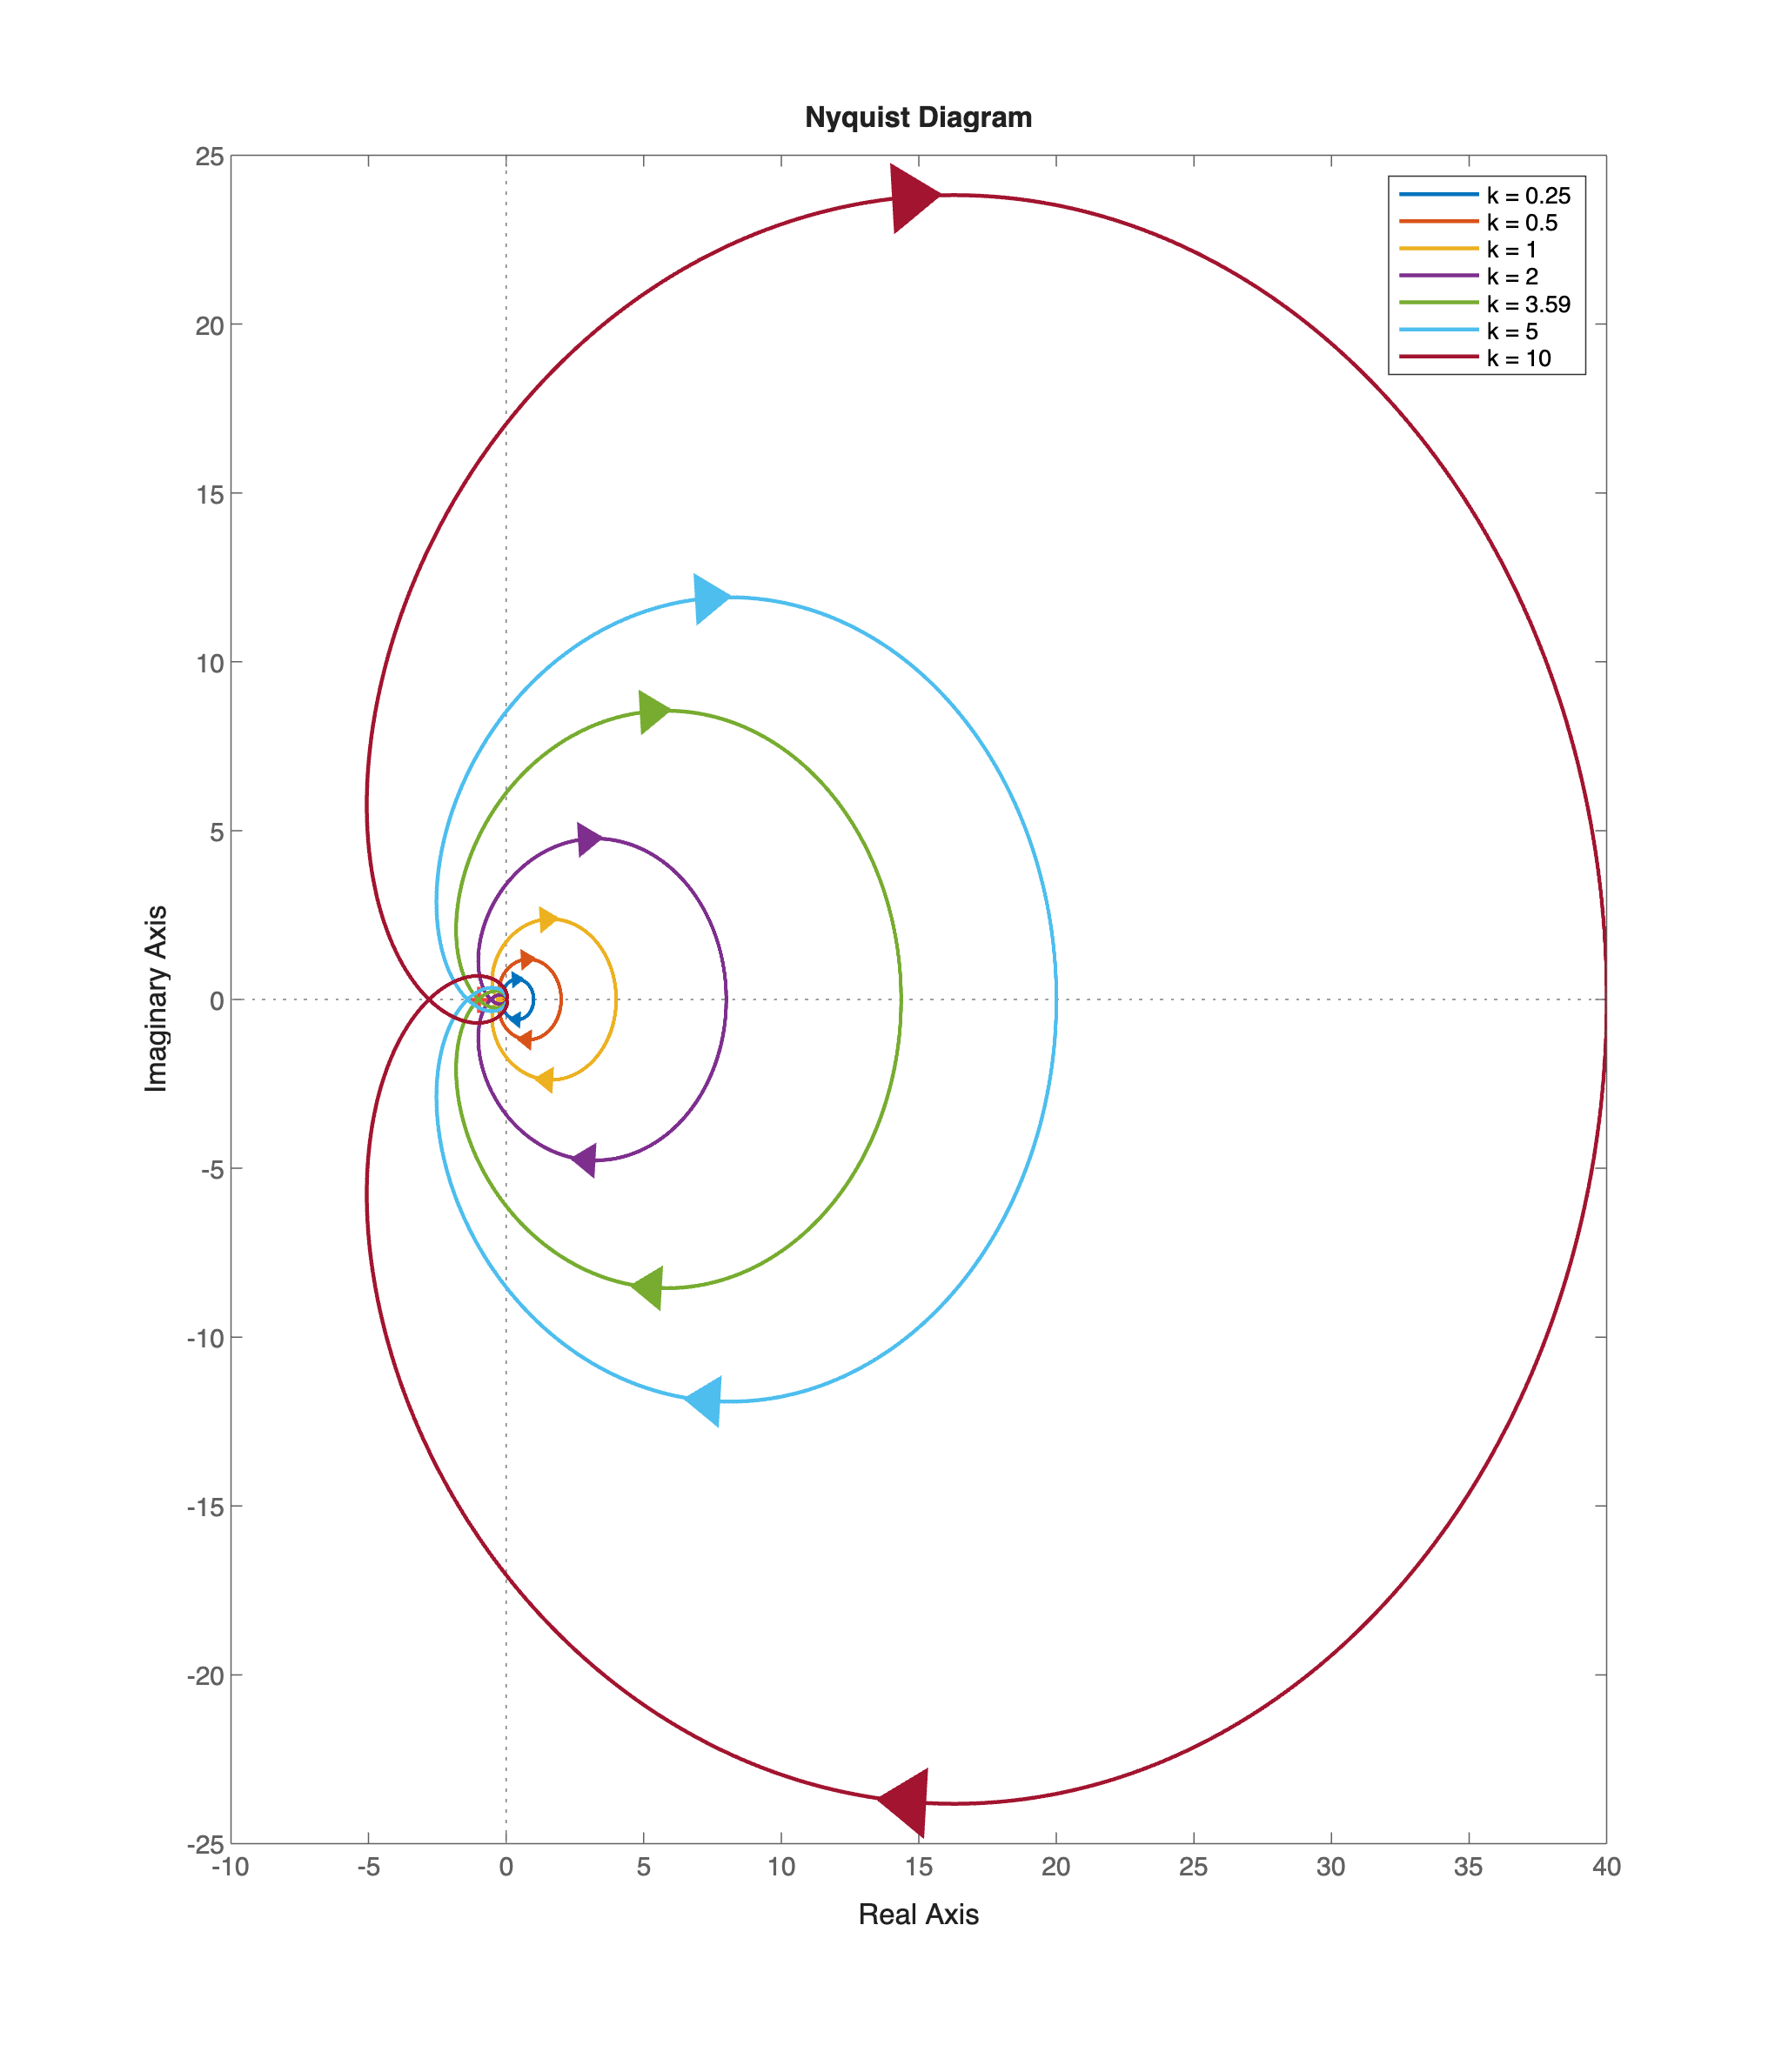

np.Responses(1).LineWidth = 1.5;

for n = 2: numel(kSET)
    k = kSET(n);
    Gs_SET{n} = k*Gs;
    addResponse(np, Gs_SET{n}, omVALS);
    np.Responses(n).LegendDisplay = "on";
    np.Responses(n).Name = ['k = ', num2str(kSET(n), 3),' '];
    np.Responses(n).LineWidth = 1.5;
end % for n

Let's put in evidence the zone around the point $-1+j0$:

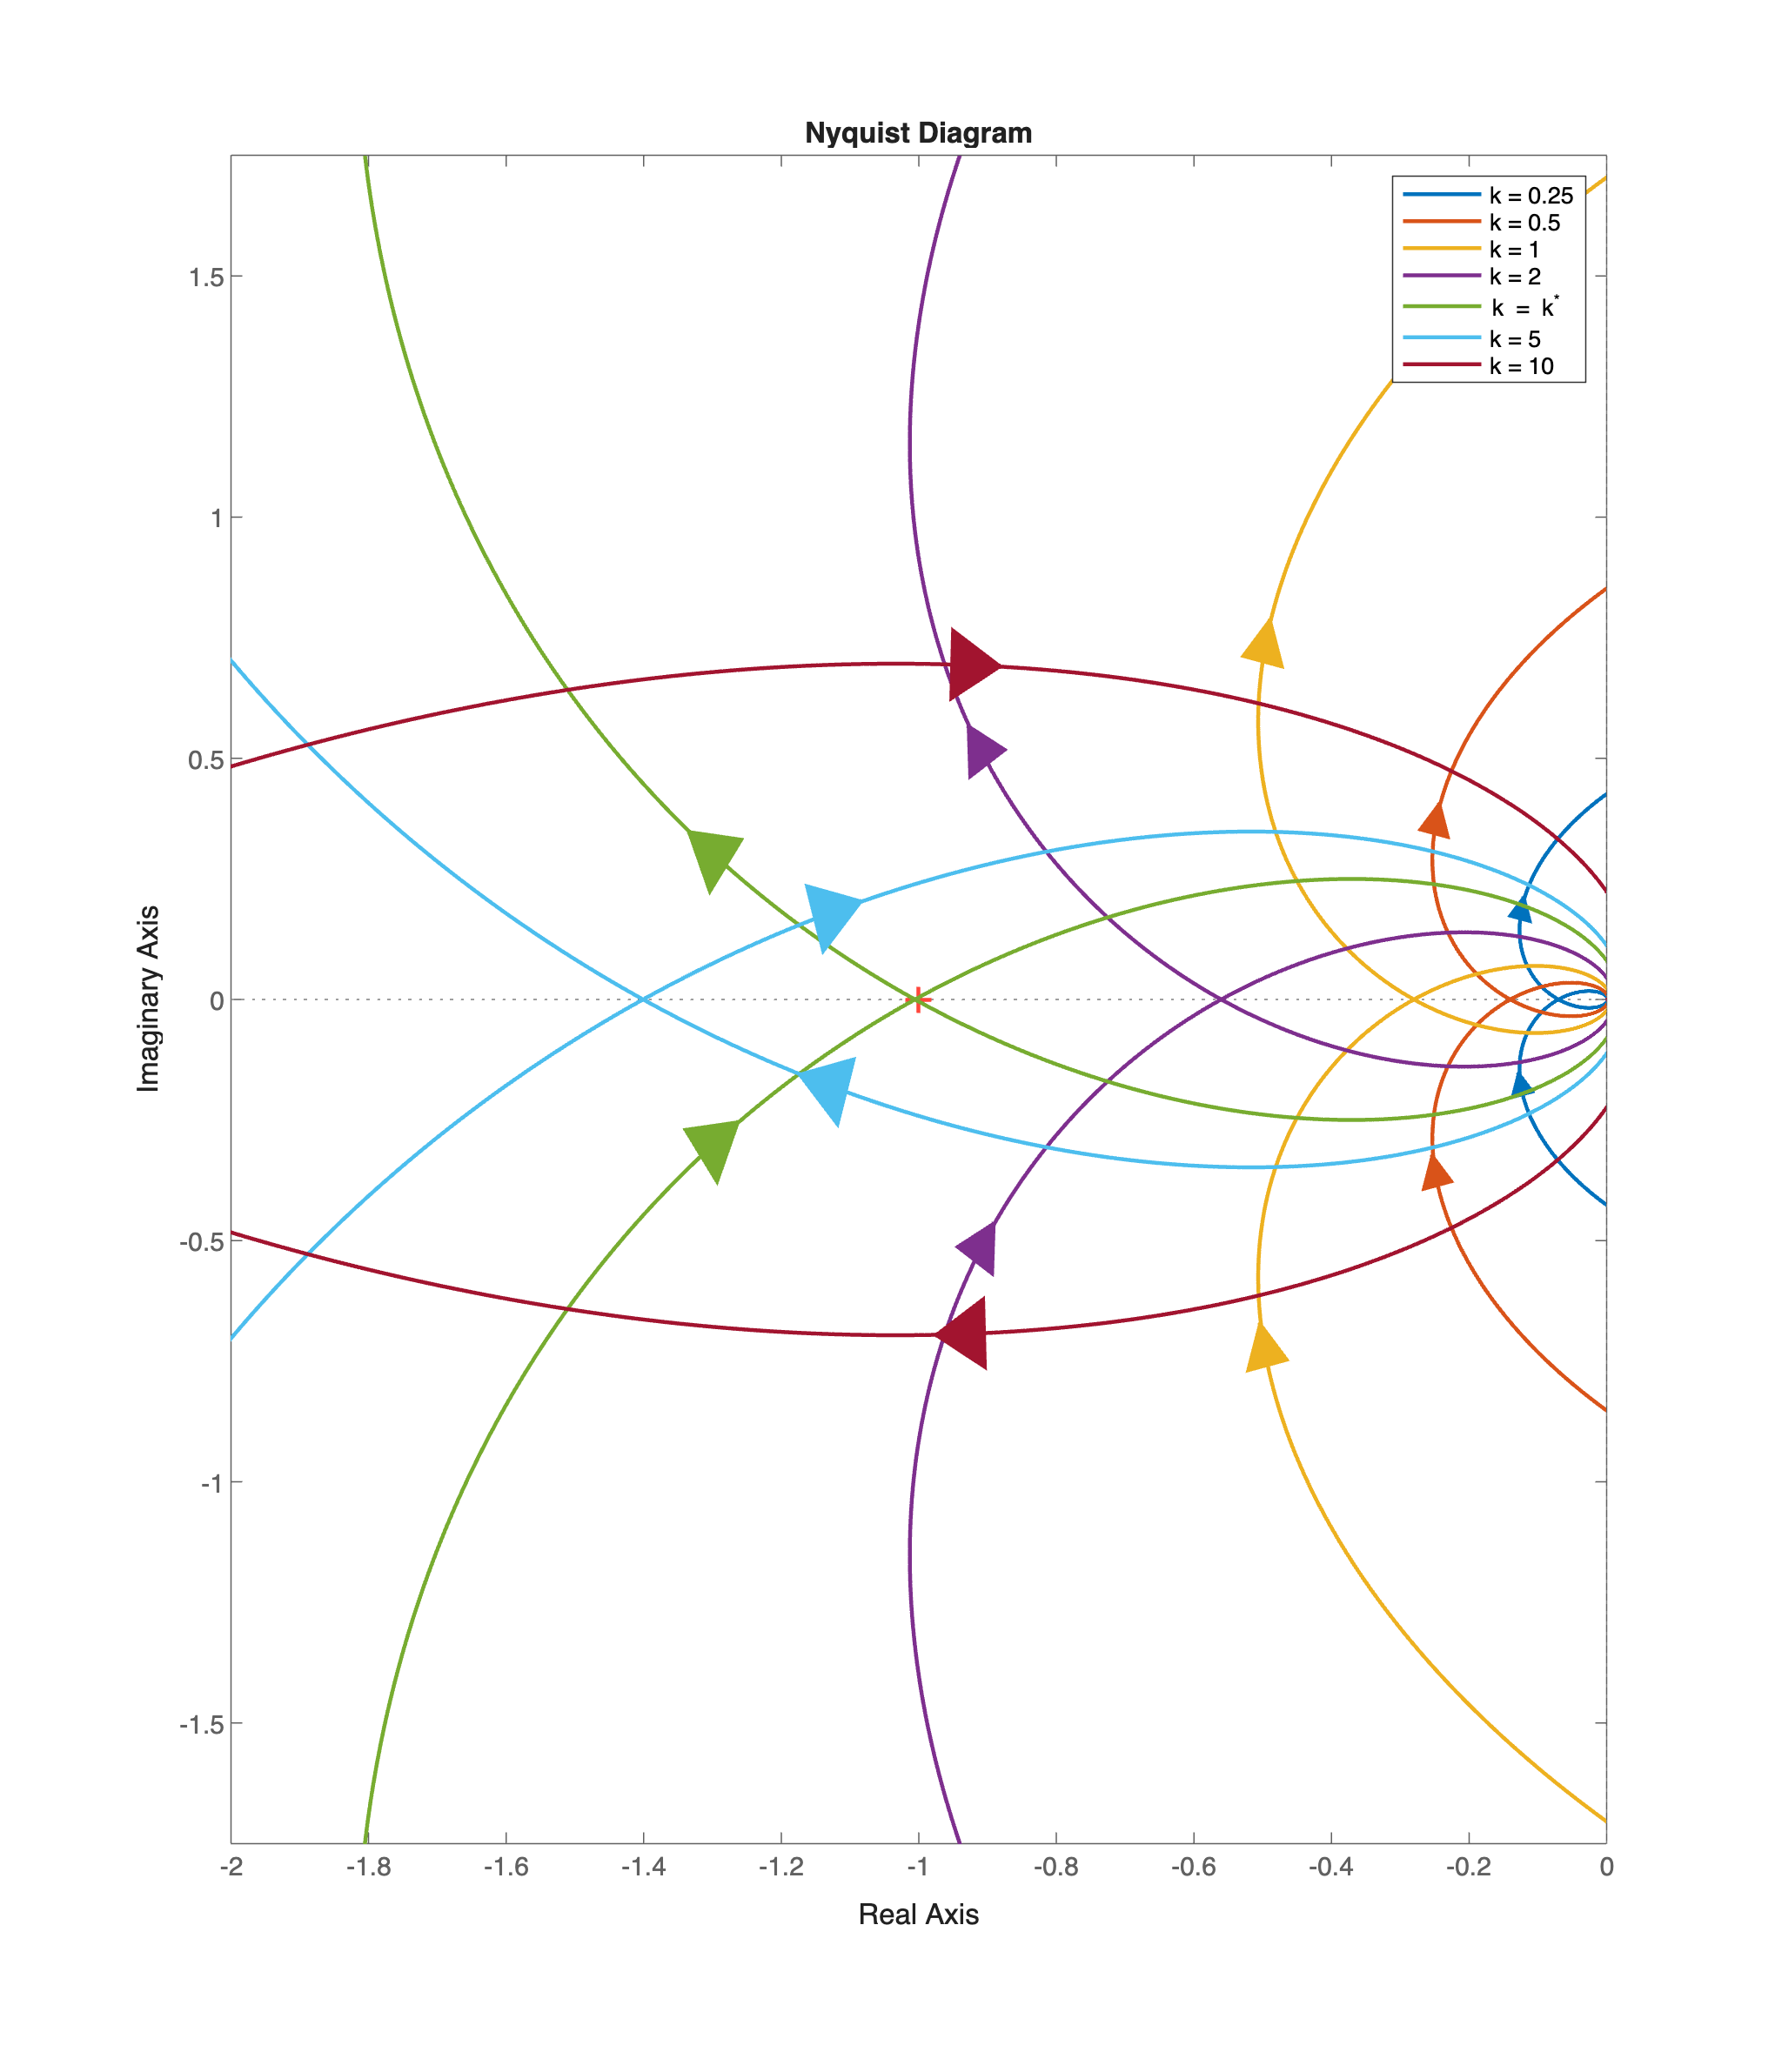

% let's plot the Nyquist diagrams, varying the gain k
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram
zoom on;

k = kSET(1);
Gs_SET{1} = k*Gs;
Gs_SET{1}.Name = ['k = ', num2str(kSET(1)),' '];
np = nyquistplot(ax, Gs_SET{1}, omVALS);
np.LegendVisible = "on";
np.Responses(1).LineWidth = 1.5;

for n = 2: numel(kSET)
    k = kSET(n);
    Gs_SET{n} = k*Gs;
    addResponse(np, Gs_SET{n}, omVALS);
    np.Responses(n).LegendDisplay = "on";
    if (n==5)
        np.Responses(n).Name = ['k = k^* '];
    else
        np.Responses(n).Name = ['k = ', num2str(kSET(n), 3),' '];
    end
    np.Responses(n).LineWidth = 1.5;
end % for n

np.XLimits = [-2, 0];
np.YLimits = [-1.75, +1.75];

**Remark**: As $k$ increases from values less than $1$ to larger values, the point on the Nyquist diagram where the frequency response is negative real shifts from near the origin, crossing exactly $(-1+j0)$ when $k= k^{*}$ and then moving away from $(-1+j0)$ as $k$ increases.

## Example 2 - Analyse $G(j\omega_{c})$when Varying the Open-Loop Transfer Function Gain

Consider the LTI system described by the strictly proper transfer function


$$G(s) = k\,\frac{\left(1-\frac{s}{2}\right)\,\left(1+\frac{s}{3}\right)}{\left(1+s\right)^{2}\,\left(1+10\,s\right)\,\left(1+\frac{s}{10}\right)}\;,\quad k > 0$$


Let's define $\omega_{c}: $ $\omega$ such that $\vert G(j\omega_{c})\vert = 1$ , i.e. the frequency response has unit modulus for $\omega = \omega_{c}$.

Let us identify the points where the frequency response has unitary magnitude on the following graph as intersections between the Nyquist diagram and a circle with a unitary radius and centre at the origin. What happens if we vary the gain $k$, for example if $k = 0.25,\, 0.5,\, 1,\, 2,\, \bar{k},\, 5,\, 10
$, where $\bar{k} = 10^{-11.1/20} \approx 3.59$? Do these characteristic points of the frequency response Nyquist diagram move around when we vary the gain $k$ ?

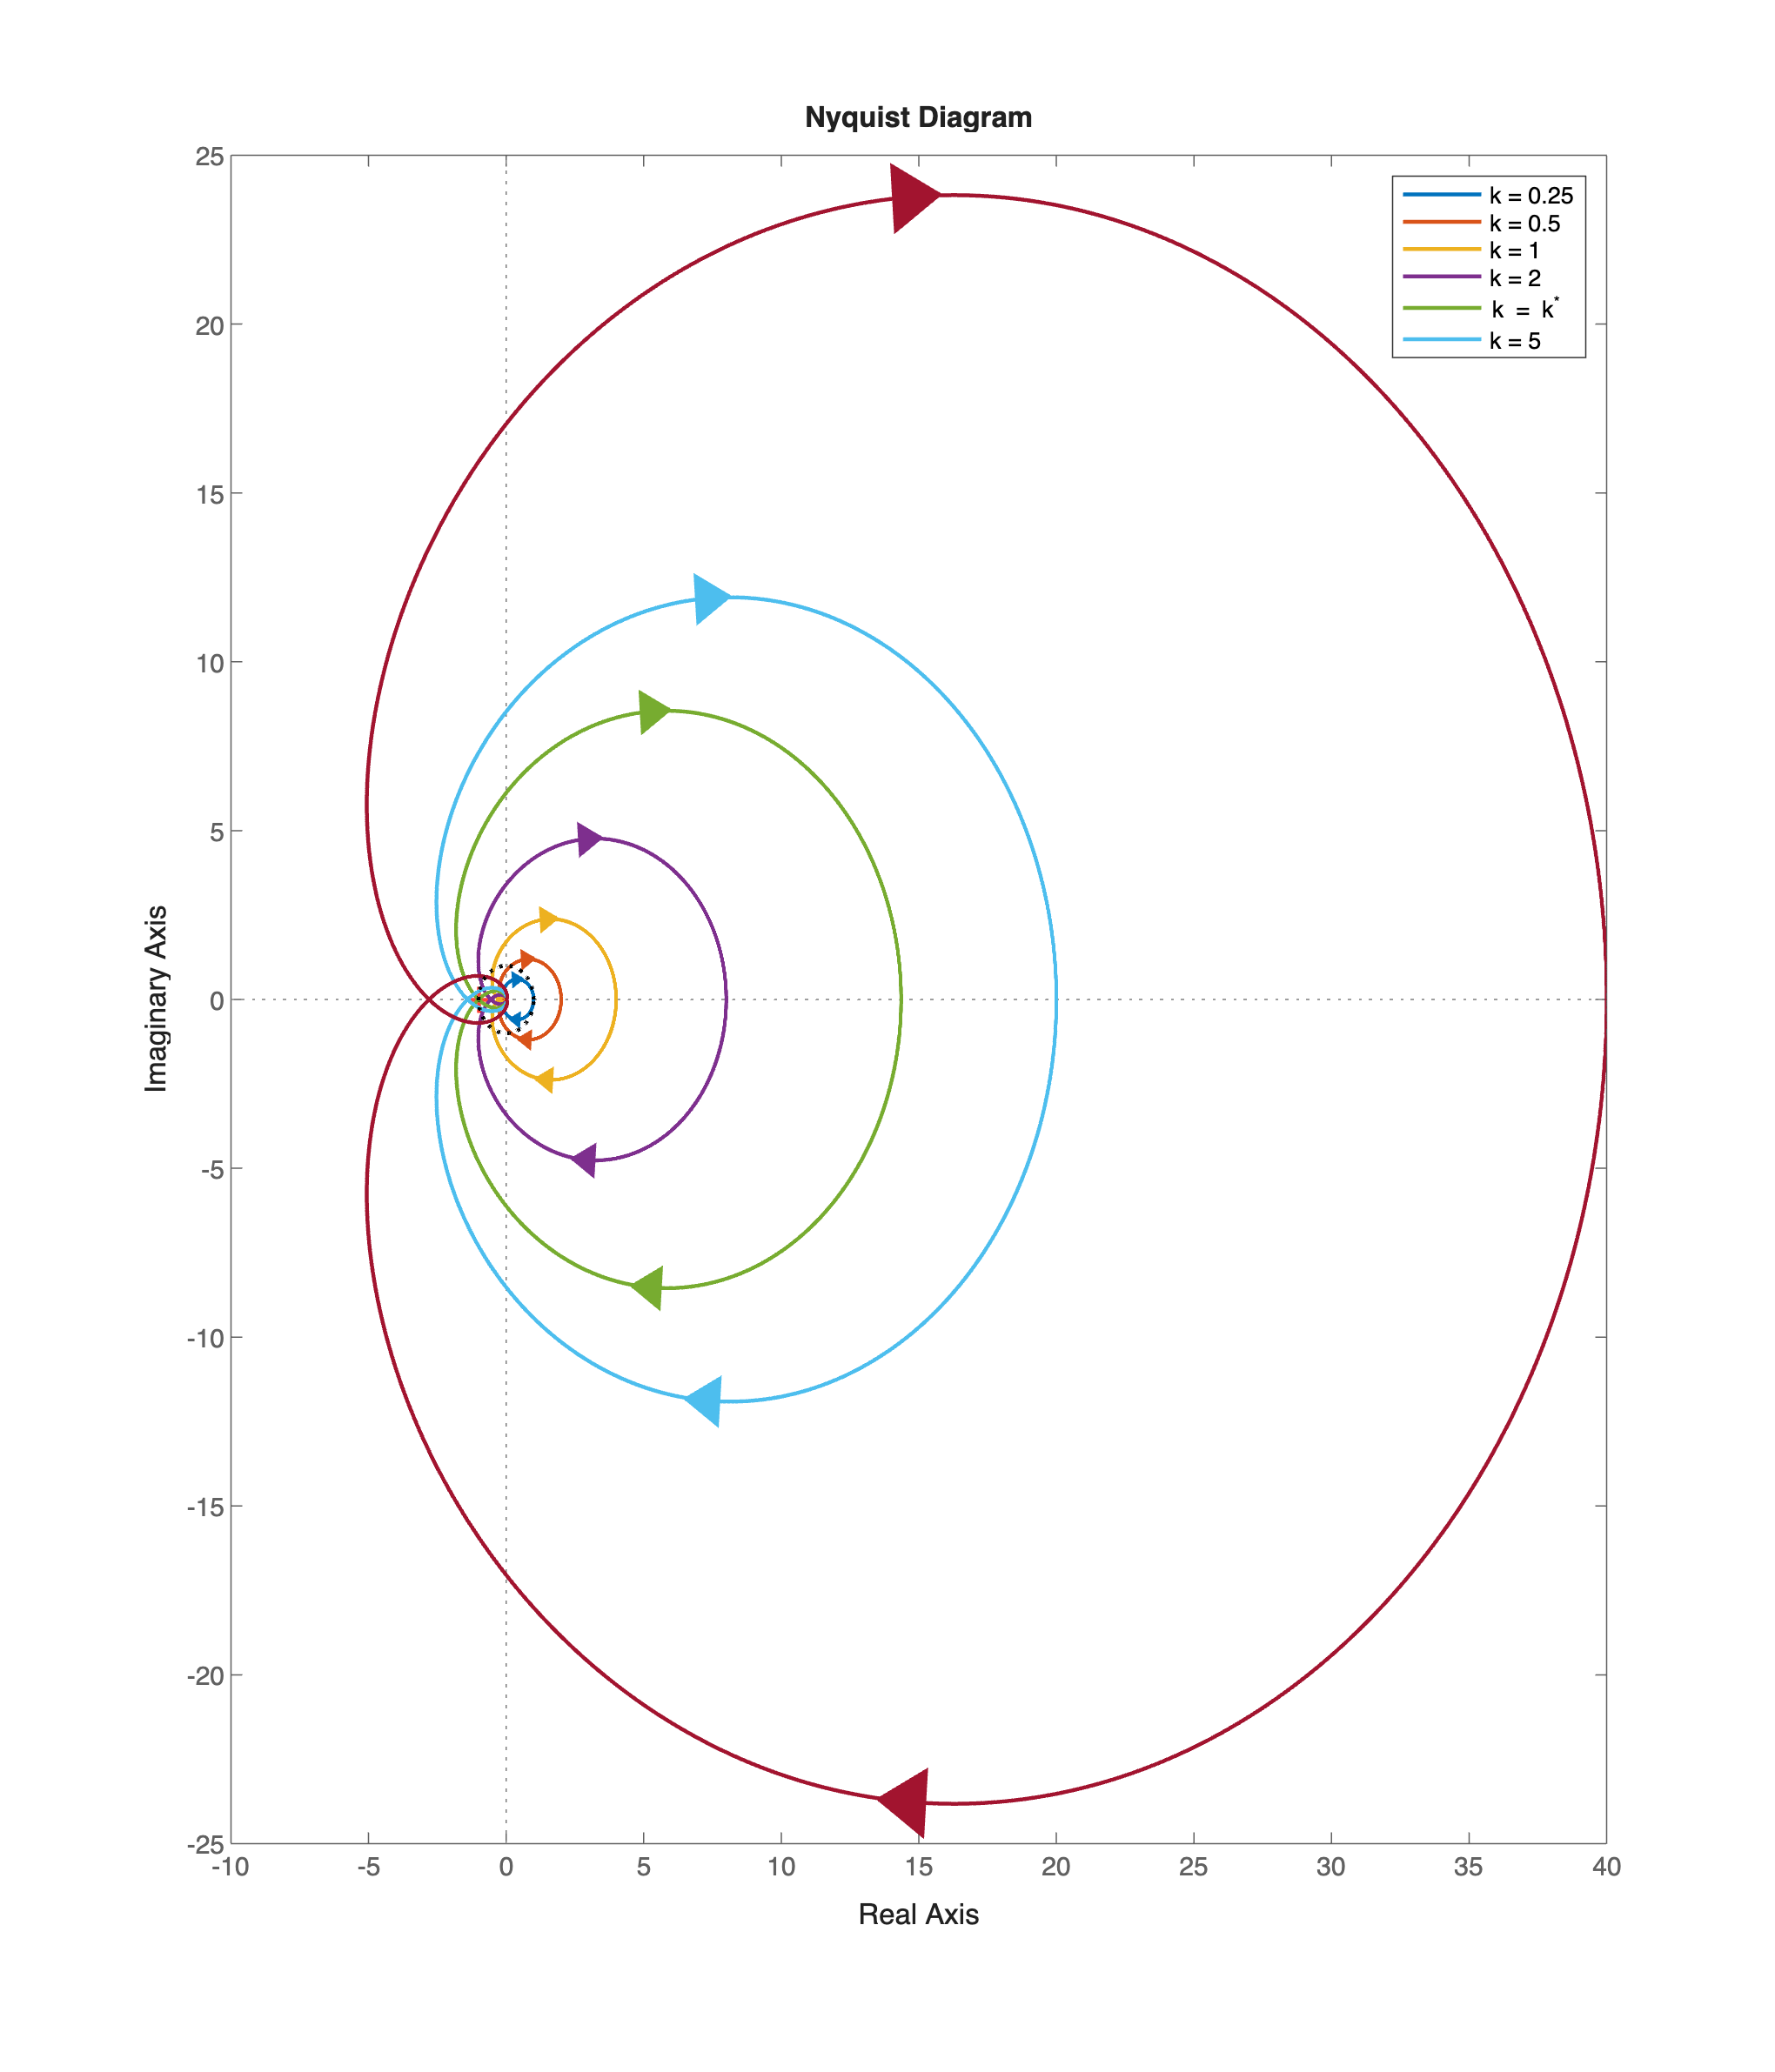

clear
close all

s=tf('s');
Gs = 4*(1-s/2)*(1+s/3)/((1+s)^2*(1+10*s)*(1+s/10));


k_lim = 10^(11.1/20); % the "magic" gain

kSET = [0.25, 0.5, 1, 2, k_lim, 5, 10];

% let's plot the Nyquist diagrams, varying the gain k
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram
hold on;
zoom on;

plotCircle(ax, [0,0],1,[0,0,0], ':', 1.5);

omVALS = logspace(-8,6,1e4); % a set of angular frequencies

k = kSET(1);
Gs_SET{1} = k*Gs;
Gs_SET{1}.Name = ['k = ', num2str(kSET(1)),' '];
np = nyquistplot(ax, Gs_SET{1}, omVALS);
np.LegendVisible = "on";
np.Responses(1).LineWidth = 1.5;

for n = 2: numel(kSET)
    k = kSET(n);
    Gs_SET{n} = k*Gs;
    addResponse(np, Gs_SET{n}, omVALS);
    np.Responses(n).LegendDisplay = "on";
    if (n==5)
        np.Responses(n).Name = ['k = k^* '];
    else
        np.Responses(n).Name = ['k = ', num2str(kSET(n), 3),' '];
    end
    np.Responses(n).LineWidth = 1.5;
end % for n

Let's put in evidence the zone around the point $-1+j0$:

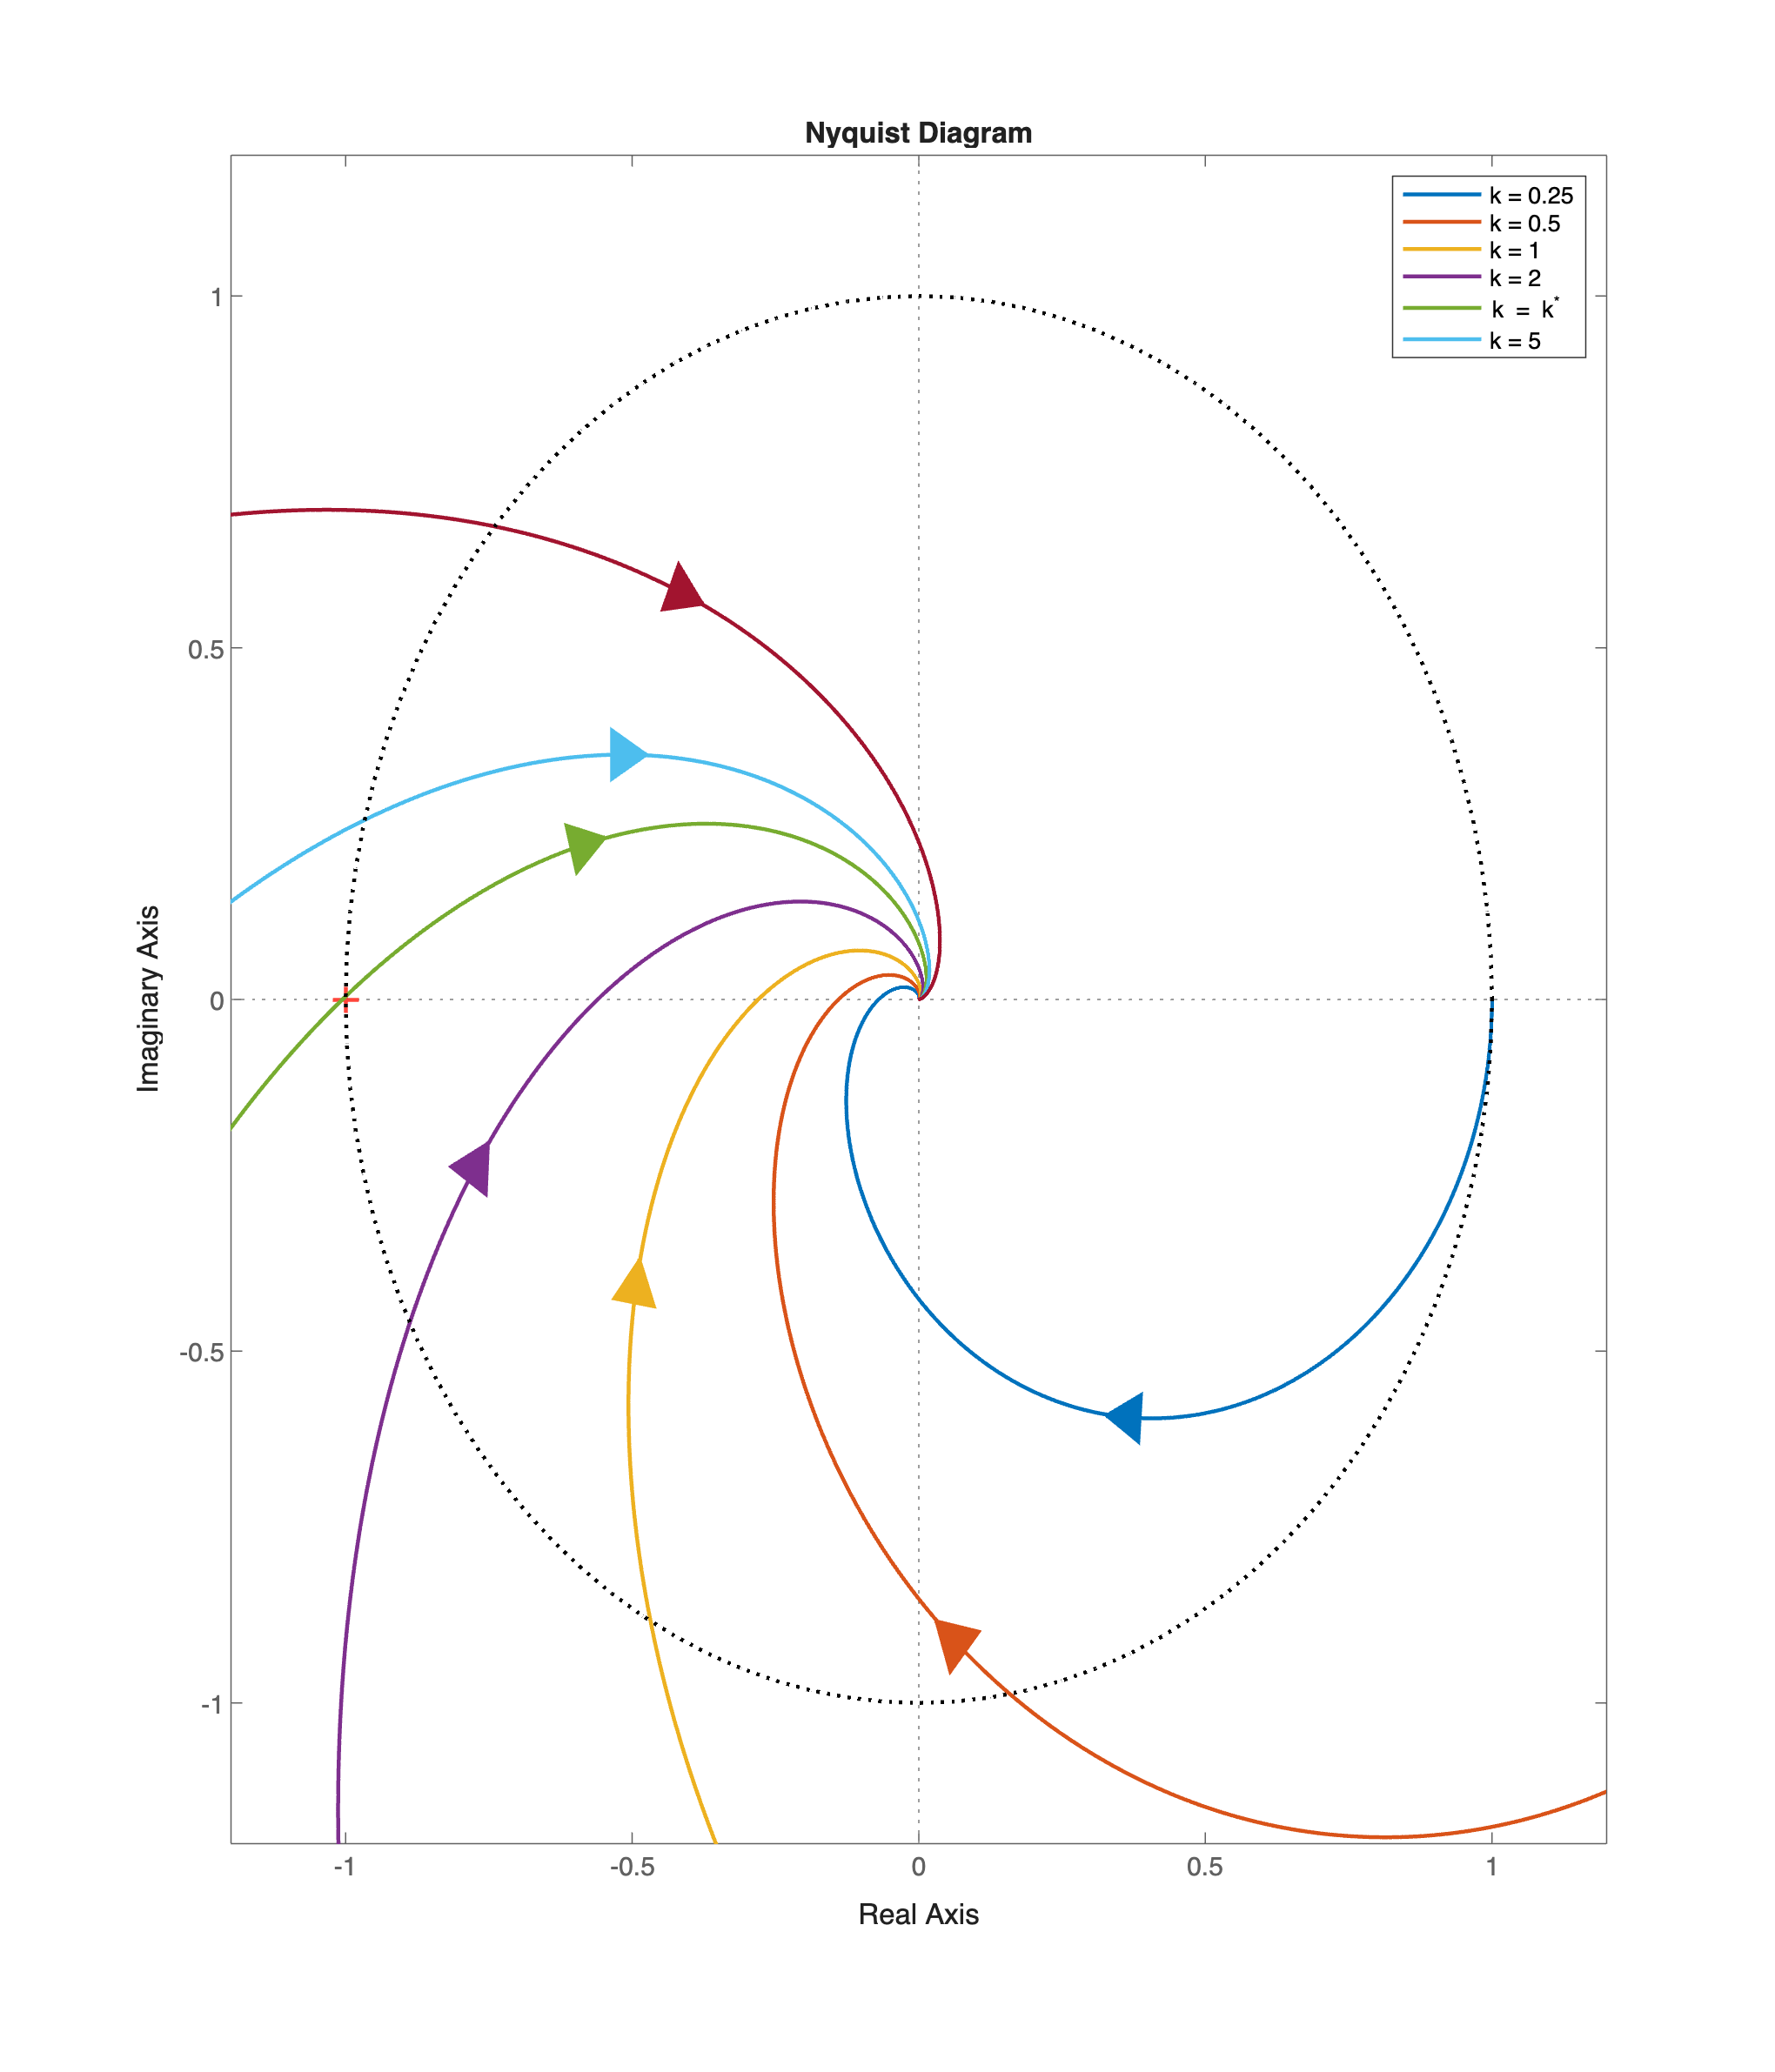

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
ax = axes('Parent',hf); % the axes used to plot each Nyquist diagram
hold on;
zoom on;

plotCircle(ax, [0,0],1,[0,0,0], ':', 1.5);

omVALS = logspace(-8,6,1e4); % a set of angular frequencies

k = kSET(1);
Gs_SET{1} = k*Gs;
Gs_SET{1}.Name = ['k = ', num2str(kSET(1)),' '];
np = nyquistplot(ax, Gs_SET{1}, omVALS);
np.LegendVisible = "on";
np.Responses(1).LineWidth = 1.5;

for n = 2: numel(kSET)
    k = kSET(n);
    Gs_SET{n} = k*Gs;
    addResponse(np, Gs_SET{n}, omVALS);
    np.Responses(n).LegendDisplay = "on";
    if (n==5)
        np.Responses(n).Name = ['k = k^* '];
    else
        np.Responses(n).Name = ['k = ', num2str(kSET(n), 3),' '];
    end
    np.Responses(n).LineWidth = 1.5;
end % for n

% let's modify the view
p = getoptions(np);
p.ShowFullContour = 'off';
p.XLim = {[-1.2, 1.2]};
p.YLim = {[-1.2, 1.2]};
setoptions(np,p);

**Remark**: When $k$ increases from values less than $1$ to larger values, the point on the Nyquist diagram where the frequency response has unit modulus rotates from $(1+j0)$, passing through precisely the point $(-1+j0)$ for $k=\bar k$ and then moving away from $(-1+j0)$ as $k$ increases further. 

function plotCircle(ax, Centre,radius,Color, Line_Style, Line_Width)
    xc = Centre(1); yc = Centre(2);
    r = radius;
    LineSty = Line_Style;
    LineW = Line_Width;
    LineCol = Color;

    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + xc;
    yunit = r * sin(th) + yc;
    plot(ax, xunit, yunit, 'Color', LineCol, 'LineStyle', LineSty, ...
        'LineWidth',LineW, 'HandleVisibility','off');
    % in this way (using 'HandleVisibility') the circle doesn't have any
    % legend -- see https://stackoverflow.com/questions/13685967/how-to-show-legend-for-only-a-specific-subset-of-curves-in-the-plotting.

end % function